# ERC Water Futures

## Setting up EPANET-MATLAB Toolkit

### **How to ask for help**

There is an online community, which is actively supported by KIOS. You can ask for comments and help at [http://community.wateranalytics.org](http://community.wateranalytics.org)

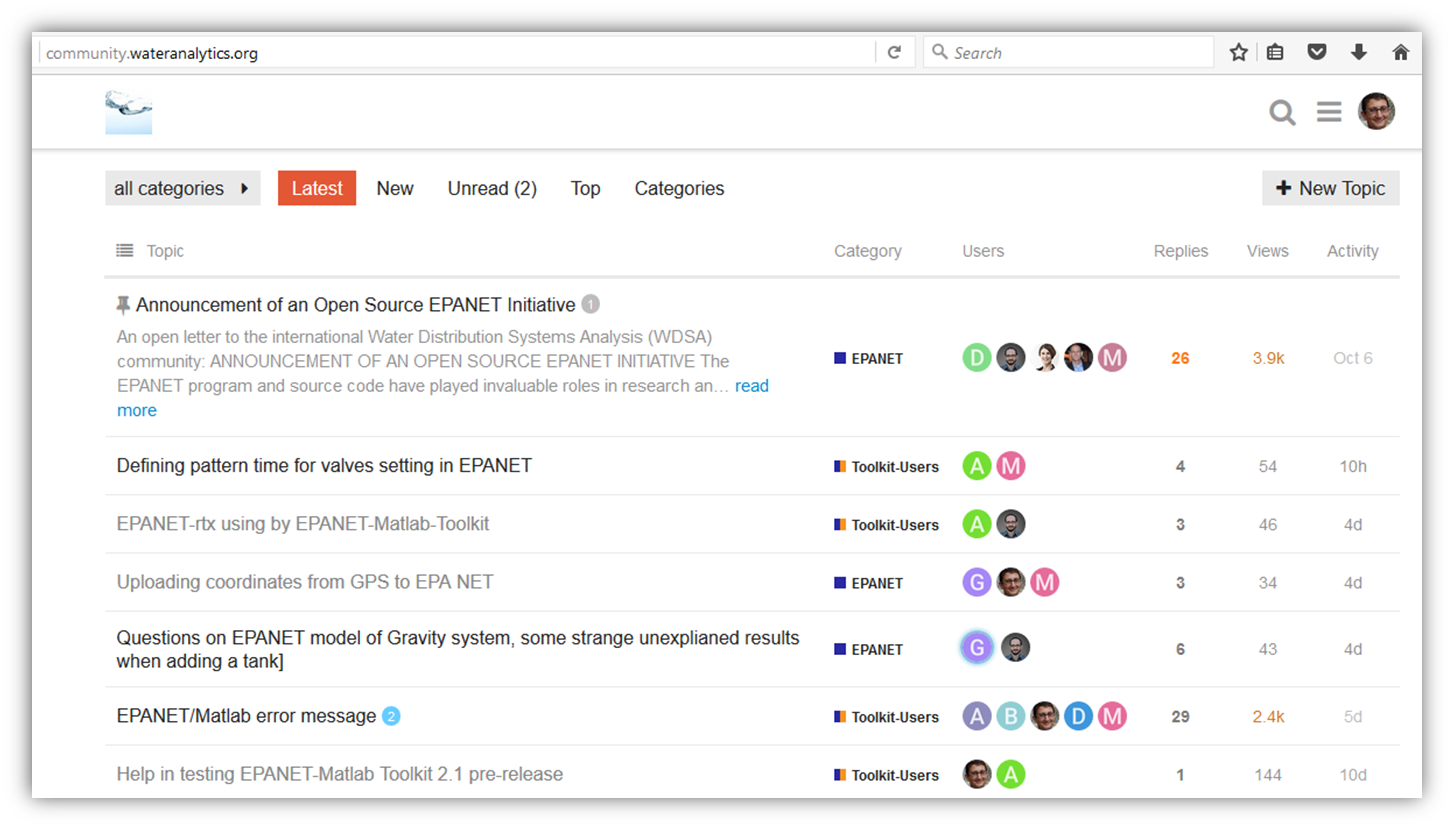

### **Download **

You can download the latest version from [https://github.com/OpenWaterAnalytics/EPANET-Matlab-Toolkit/releases](https://github.com/OpenWaterAnalytics/EPANET-Matlab-Toolkit/releases)

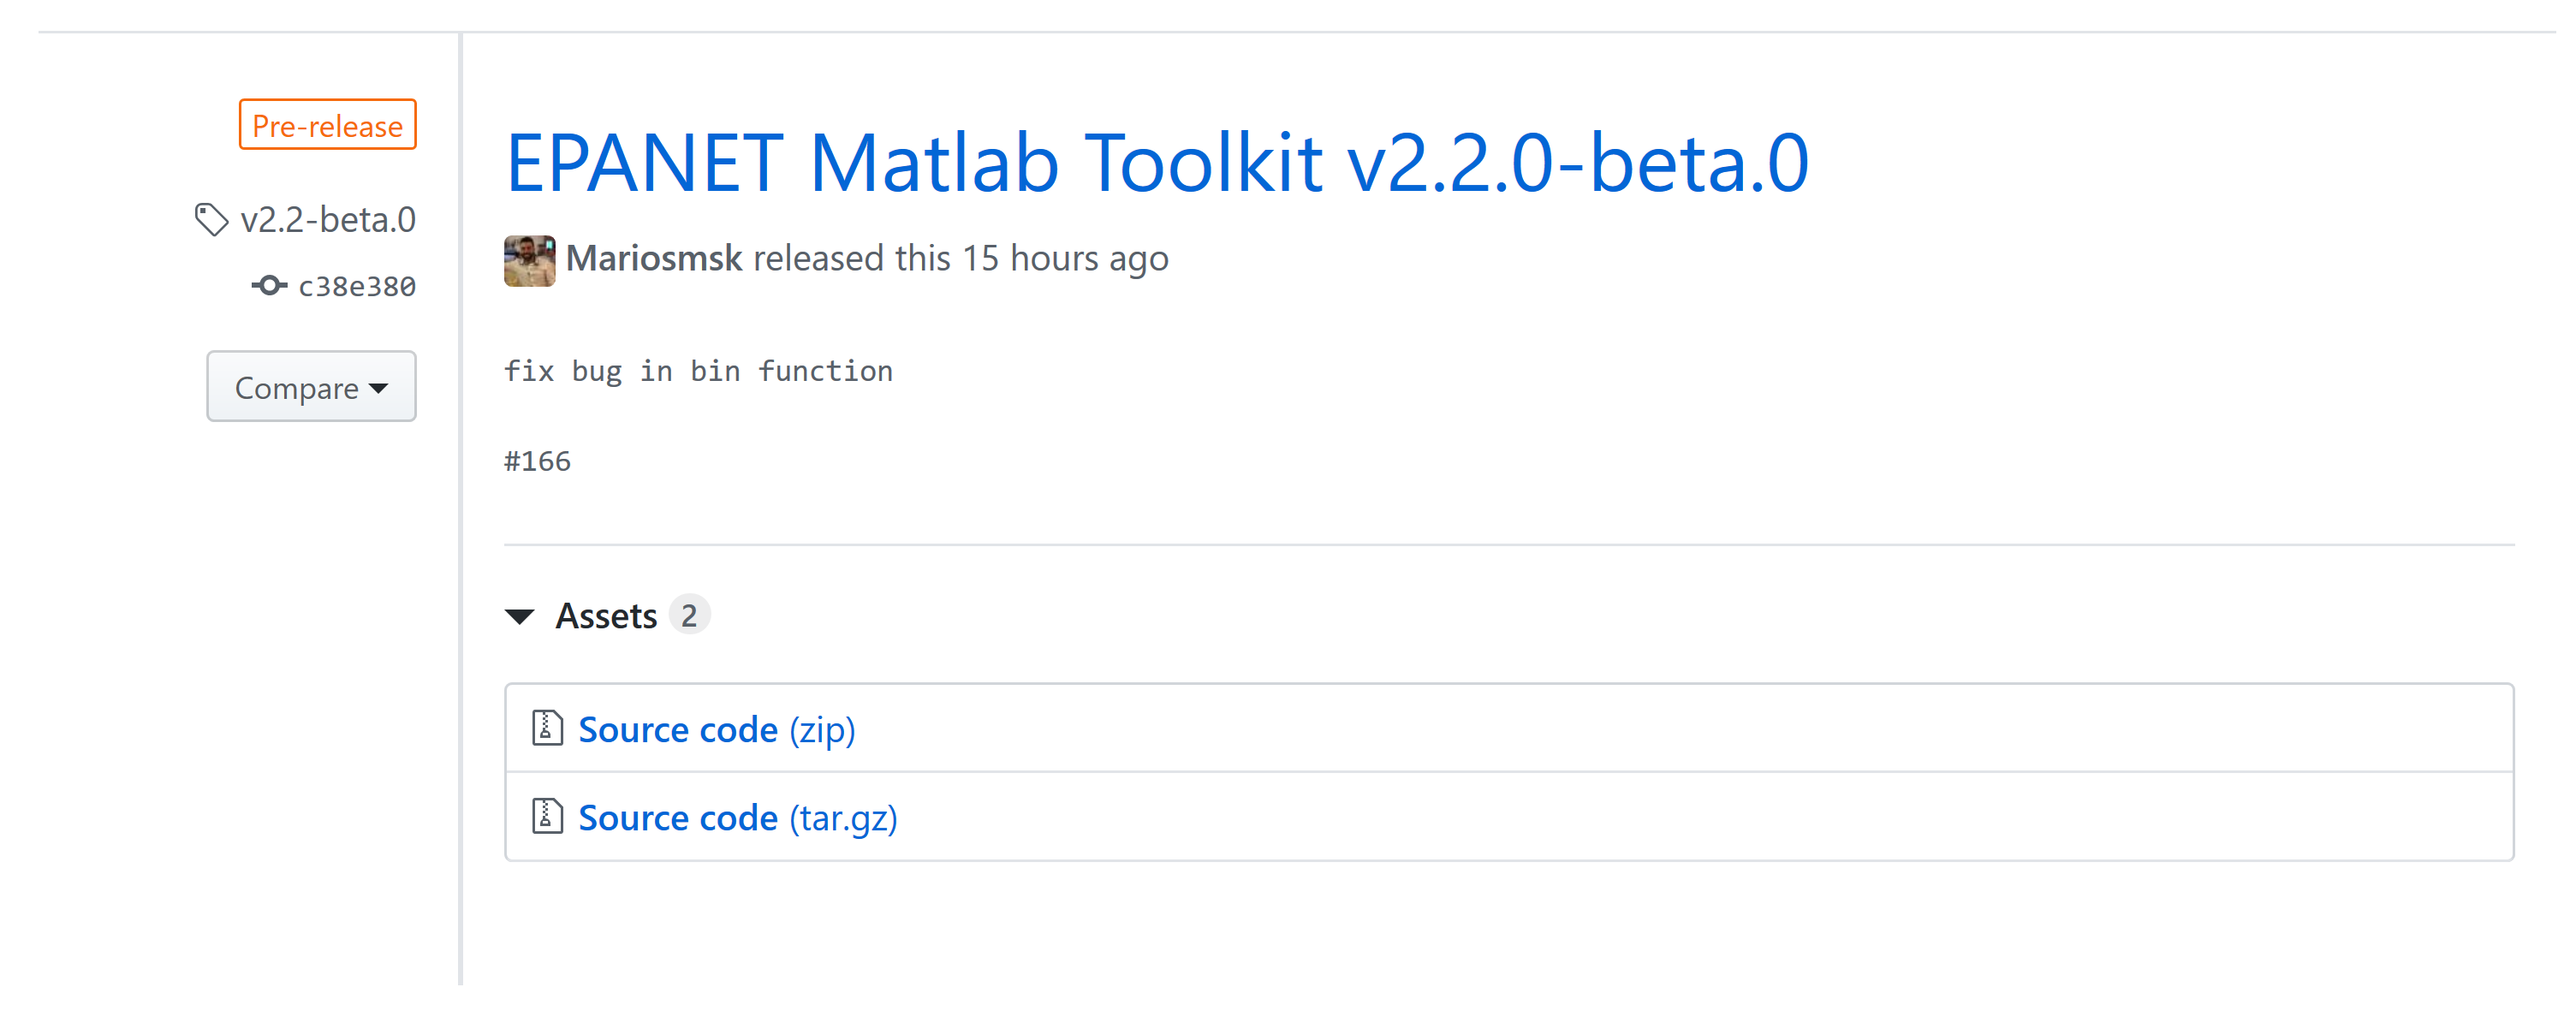

### **Stucture of the Toolkit**

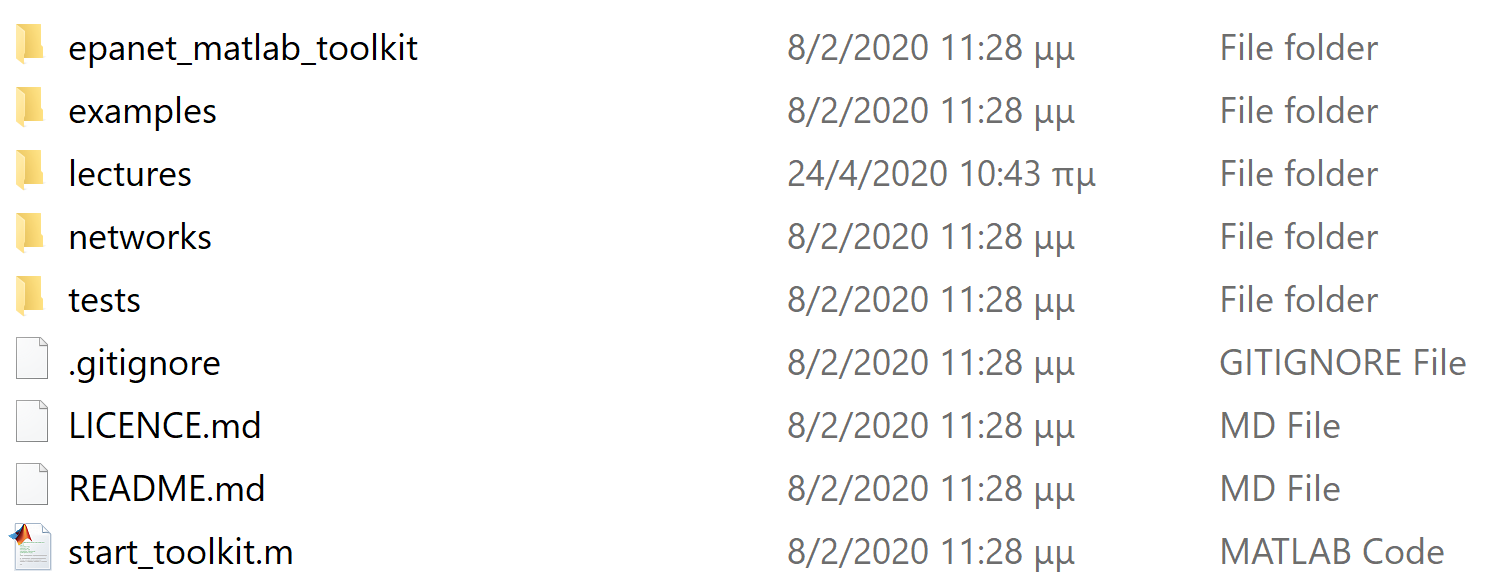

### **Installation of the MinGW-w64 Compiler for MATLAB**

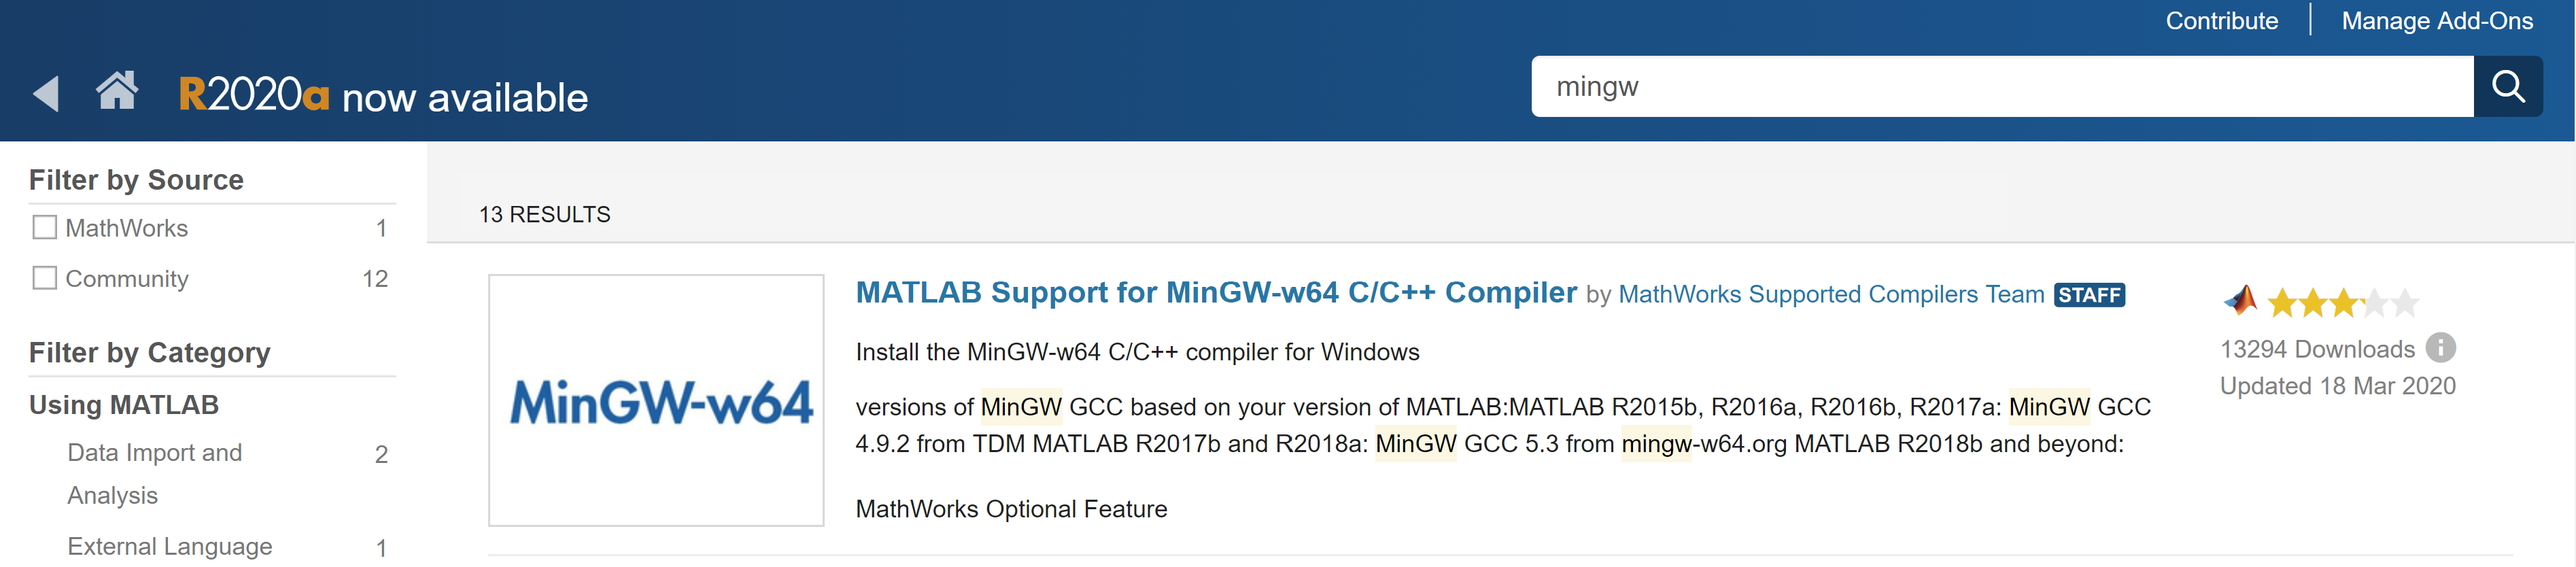

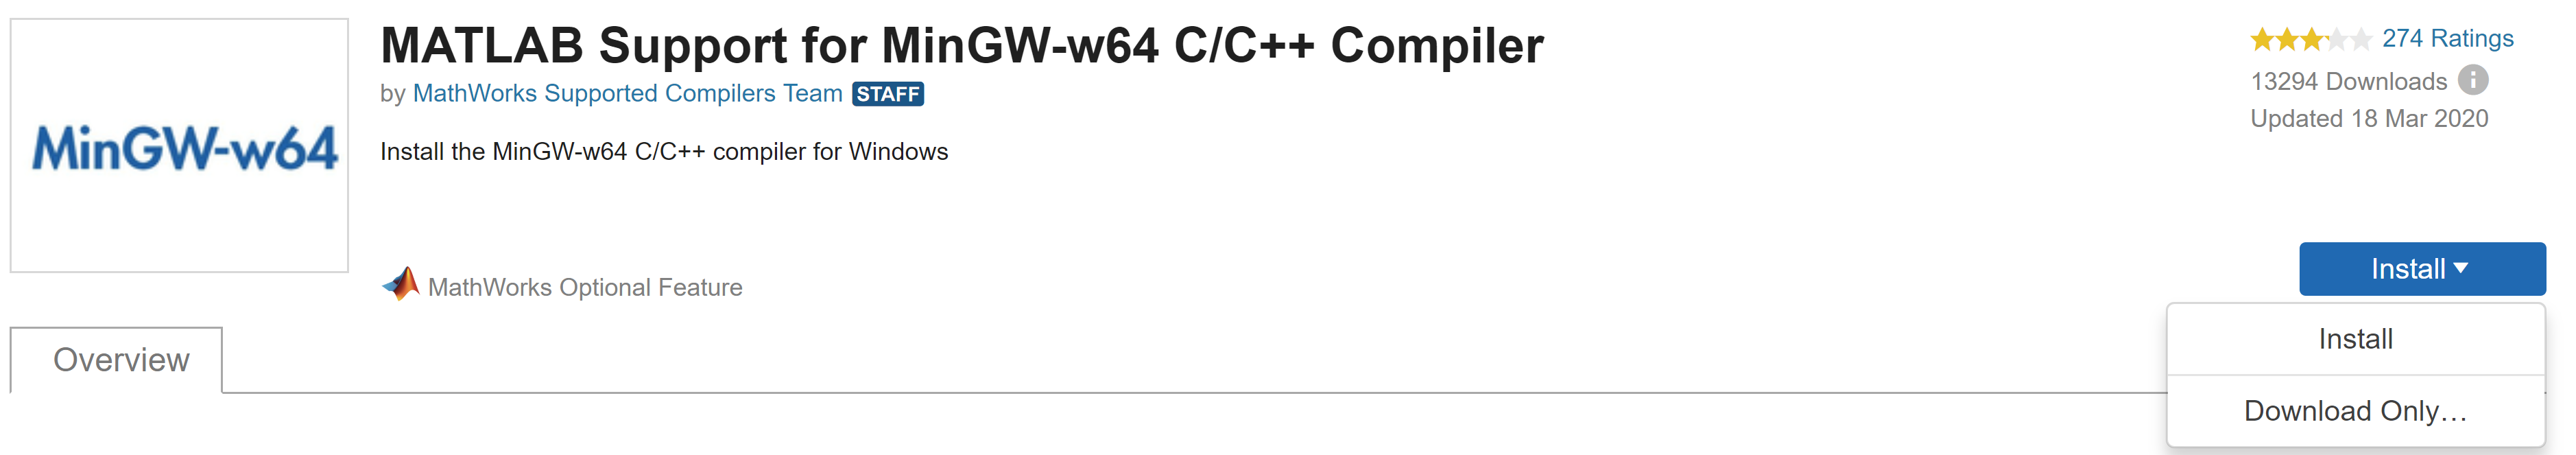

mex -setup

MEX configured to use 'MinGW64 Compiler (C)' for C language compilation.

To choose a different language, select one from the following:
 mex -setup C++ 
 mex -setup FORTRAN


`If this has been correctily configured, you should see the following:`

`MEX configured to use 'MinGW64 Compiler (C)' for C language compilation.`

`To choose a different language, select one from the following:`

` mex -setup C++ `

` mex -setup FORTRAN`

**Install  Compiler Error Message**

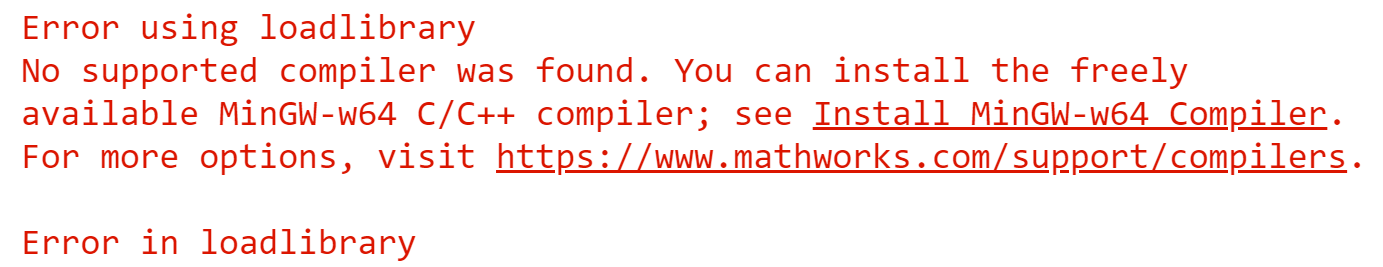

### **Initialize EPANET-MATLAB Toolkit**

Load all the paths in MATLAB. You should always begin with this command to load the toolkit.

start_toolkit

EPANET-MATLAB Toolkit Paths Loaded.


If you get an error message:

`'start_toolkit' is not found in the current folder or on the MATLAB path, but exists in:`

It means that you need to change the MATLAB current folder.

**Load a benchmark network**

Decide which benchmark network to use and load the network

% decide which network to load from the "/networks/" folder  
filename = 'L-TOWN.inp'; % you can also try 'L-TOWN.inp', 'Net3.inp', etc.

%call epanet class and load all data and functions in G structure
G = epanet(filename)

EPANET version {20200} loaded (EMT version {dev2.2}).
Loading File "L-TOWN.inp"...
Input File "L-TOWN.inp" loaded sucessfuly.


G =   epanet with properties:

                   ControlLevelValues: [3.9000 2.4000]
                     ControlLinkIndex: [906 906]
                     ControlNodeIndex: [785 785]
                         ControlRules: []
                    ControlRulesCount: 2
                             Controls: [1×2 struct]
                      ControlSettings: [0 1]
                         ControlTypes: {'HIGHLEVEL'  'LOWLEVEL'}
                    ControlTypesIndex: [1 0]
                           CurveCount: 1
                           CurvesInfo: [1×1 struct]
                      DemandModelCode: 0
                      DemandModelPmin: 0
                      DemandModelPreq: 0.1000
                      DemandModelPexp: 0.5000
                      DemandModelType: {'DDA'}
                EnergyEfficiencyUnits: 'percent'
                          EnergyUnits: 'kwatt-hours'
                              Errcode: 0
      

### **Plot a network**

% Read the help file for plotting 
help G.plot

--- help for epanet/plot ---

  Plots network in a new Matlab figure
  Arguments:
  'nodes': yes/no
  'links': yes/no
  'line' : yes/no
  'point': yes/no
  'highlightnode': array of node IDs
  'highlightlink': array of link IDs
  'fontsize': number (px)
  'colornode': array of node IDs
  'colorlink': array of link id
  'axes': axes coordinates
  'linksindex': yes
  'nodesindex': yes
  'legend': show/hide
  'extend': yes/no
  'legendposition':
        'North'              inside plot box near top
        'South'              inside bottom
        'East'               inside right
        'West'               inside left
        'NorthEast'          inside top right (default for 2-D plots)
        'NorthWest'          inside top left
        'SouthEast'          inside bottom right
        'SouthWest'          inside bottom left
        'NorthOutside'       outside plot box near top
        'SouthOutside'       outside bottom
        'EastOutside'        outside right
  

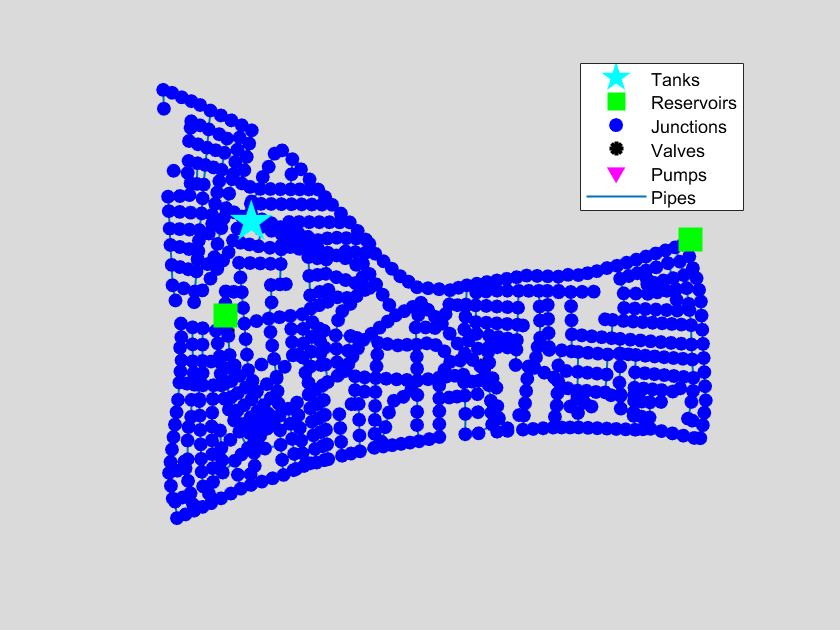


% For a simple plot, use G.plot. 
G.plot;

### **Getting information from pipes**

pipeCount = G.getLinkCount

pipeCount = int32
909

diameters = G.getLinkDiameter

diameters =    200   150   200   100   100   100   100   100   150   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   150   100   100   200   150   100   100   100   100   100   100   100   100   200   100


pipelength = G.getLinkLength(1:3)

pipelength =    26.9292   14.3481   50.1267


pipeNameID = G.getLinkNameID

pipeNameID = 1×909 cell array
  Columns 1 through 842

    {'p1'}    {'p2'}    {'p3'}    {'p4'}    {'p5'}    {'p6'}    {'p7'}    {'p8'}    {'p9'}    {'p10'}    {'p11'}    {'p12'}    {'p13'}    {'p14'}    {'p15'}    {'p16'}    {'p17'}    {'p18'}    {'p19'}    {'p20'}    {'p21'}    {'p22'}    {'p23'}    {'p24'}    {'p25'}    {'p26'}    {'p27'}    {'p28'}    {'p29'}    {'p30'}    {'p31'}    {'p32'}    {'p33'}    {'p34'}    {'p35'}    {'p36'}    {'p37'}    {'p38'}    {'p39'}    {'p40'}    {'p41'}    {'p42'}    {'p43'}    {'p44'}    {'p45'}    {'p46'}    {'p47'}    {'p48'}    {'p49'}    {'p50'}    {'p51'}    {'p52'}    {'p53'}    {'p54'}    {'p55'}    {'p56'}    {'p57'}    {'p58'}    {'p59'}    {'p60'}    {'p61'}    {'p62'}    {'p63'}    {'p64'}    {'p65'}    {'p66'}    {'p67'}    {'p68'}    {'p69'}    {'p70'}    {'p71'}    {'p72'}    {'p73'}    {'p74'}    {'p75'}    {'p76'}    {'p77'}    {'p78'}    {'p79'}    {'p80'}    {'p81'}    {'p82'}    {'p83'}    {'p84'}    {'p85'}    {'p86'}    {'p8

### **Getting information from nodes**

nodeCount = G.getNodeCount

nodeCount = int32
785

elevations = G.getNodeElevations([1, 2, 3])

elevations =    73.2105   73.8737   73.1782


demands = G.getNodeBaseDemands

demands = 1×3 cell array
    {1×785 double}    {1×785 double}    {1×785 double}


nodeID = G.getNodeNameID

nodeID = 1×785 cell array
    {'n1'}    {'n2'}    {'n3'}    {'n4'}    {'n5'}    {'n6'}    {'n7'}    {'n8'}    {'n9'}    {'n10'}    {'n11'}    {'n12'}    {'n13'}    {'n14'}    {'n15'}    {'n16'}    {'n17'}    {'n18'}    {'n19'}    {'n20'}    {'n21'}    {'n22'}    {'n23'}    {'n24'}    {'n25'}    {'n26'}    {'n27'}    {'n28'}    {'n29'}    {'n30'}    {'n31'}    {'n32'}    {'n33'}    {'n34'}    {'n35'}    {'n36'}    {'n37'}    {'n38'}    {'n39'}    {'n40'}    {'n41'}    {'n42'}    {'n43'}    {'n44'}    {'n45'}    {'n46'}    {'n47'}    {'n48'}    {'n49'}    {'n50'}    {'n51'}    {'n52'}    {'n53'}    {'n54'}    {'n55'}    {'n56'}    {'n57'}    {'n58'}    {'n59'}    {'n60'}    {'n61'}    {'n62'}    {'n63'}    {'n64'}    {'n65'}    {'n66'}    {'n67'}    {'n68'}    {'n69'}    {'n70'}    {'n71'}    {'n72'}    {'n73'}    {'n74'}    {'n75'}    {'n76'}    {'n77'}    {'n78'}    {'n79'}    {'n80'}    {'n81'}    {'n82'}    {'n83'}    {'n84'}    {'n85'}    {'n86'}    {'n87'}    {'n88'}    {'n89'}    

### **Preparing for Graph Theory**

**Compute connectivity matrix**

% connectivity matrix: how each node connects to other nodes
A = G.getConnectivityMatrix

A =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0   

**Create a network graph**

%translate the connectivity matrix into a graph structure
g = graph(A)

g =   graph with properties:

    Edges: [909×2 table]
    Nodes: [785×0 table]


g.Edges(1:5,:)

ans = 5×2 table
    EndNodes    Weight
    ________    ______

    1    347      1   
    2      3      1   
    2    352      1   
    3    353      1   
    4      9      1   


figure
plot(g)

**Compute centrality metric**

cdegree = centrality(g, 'degree')

cdegree =      1
     2
     2
     1
     2
     2
     3
     3
     2
     4


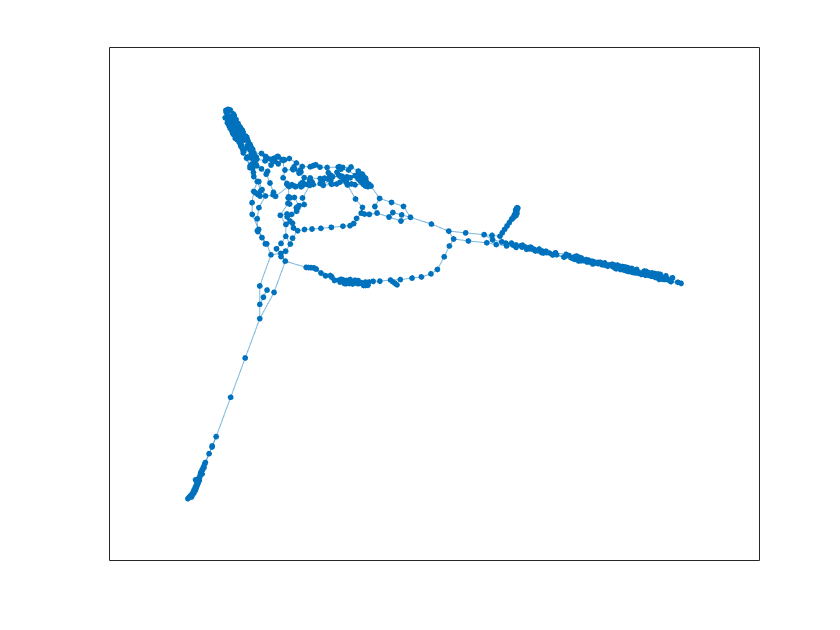

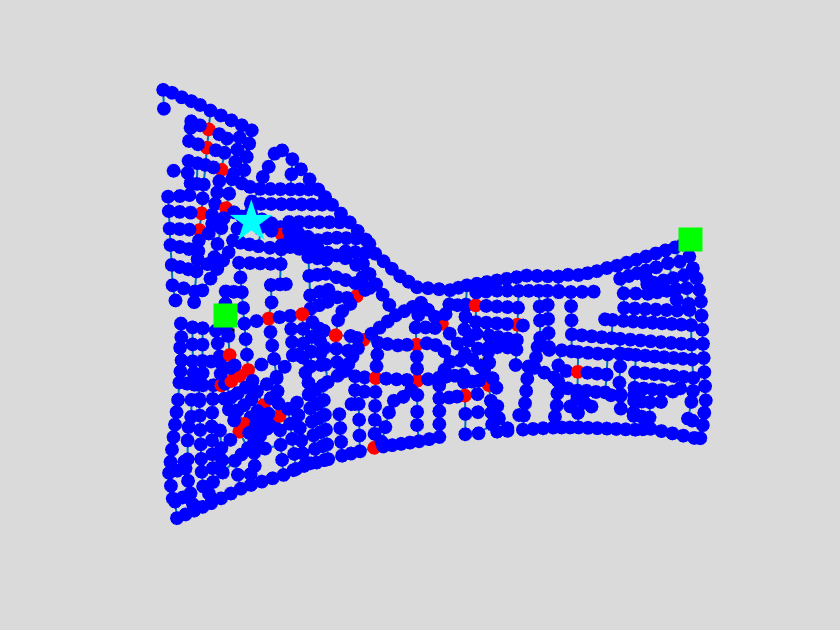

ans =   Axes with properties:

             XLim: [-135.0210 3.1055e+03]
             YLim: [-77.0330 1.7717e+03]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


G.plot('highlightnode',nodeID(cdegree>3))

### **Running your first analysis**

% set simulation duration at 48 hours 
hrs = 24 

hrs = 24

G.setTimeSimulationDuration(3600*hrs)

Execute the simulation using the batch hydraulic analysis 

H = G.getComputedTimeSeries_ENepanet

H = struct with fields:
              Time: [2017×1 double]
          Pressure: [2017×785 double]
            Demand: [2017×785 double]
              Head: [2017×785 double]
       NodeQuality: [2017×785 double]
              Flow: [2017×909 double]
          Velocity: [2017×909 double]
          HeadLoss: [2017×909 double]
            Status: [2017×909 double]
           Setting: [2017×909 double]
      ReactionRate: [2017×909 double]
    FrictionFactor: [2017×909 double]
       LinkQuality: [2017×909 double]


**Plot results**

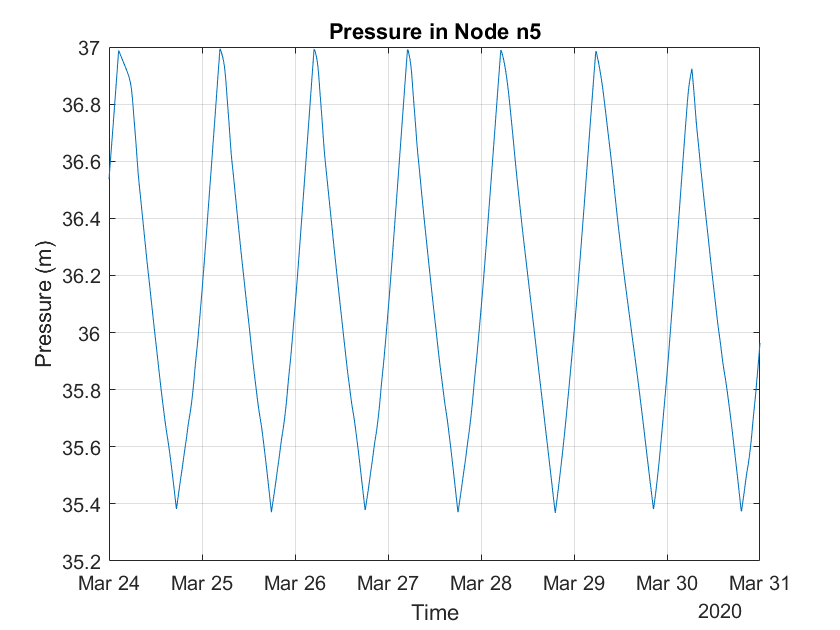

% Get pressure in meters
P = H.Pressure;
F= H.Flow;

% Translate time to plots 
T = H.Time;
TD = datetime(2020,3,24,0,0,T); 

% Plot
figure
plot(TD,P(:,5))
grid on
title(['Pressure in Node ',G.getNodeNameID{5}])
ylabel('Pressure (m)')
xlabel('Time')

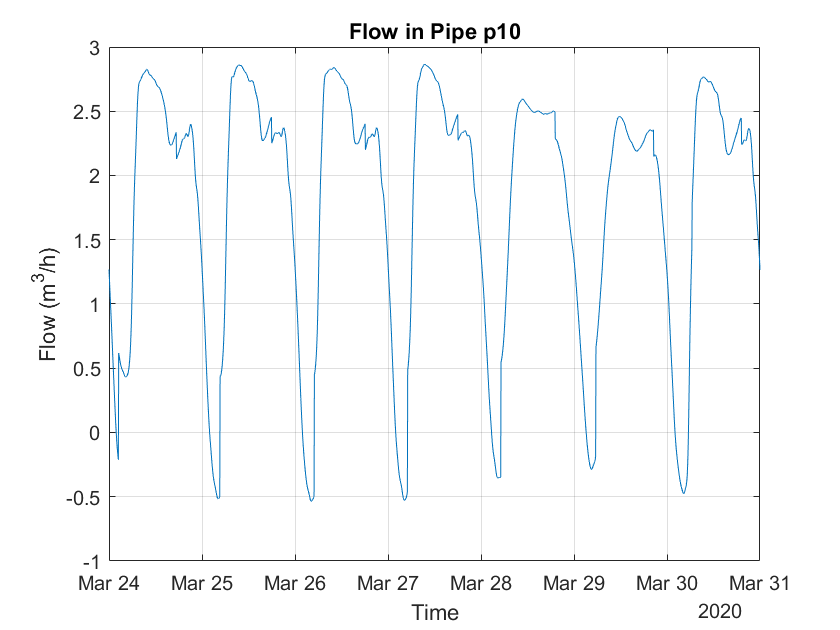


figure
plot(TD,F(:,10))
grid on
title(['Flow in Pipe ',G.getLinkNameID{10}])
ylabel('Flow (m^3/h)')
xlabel('Time')

## **Sensitivity analysis using Monte Carlo Analysis**

% Load network
G = epanet('net2-cl2.inp')

EPANET version {20200} loaded (EMT version {dev2.2}).
Loading File "net2-cl2.inp"...
Input File "net2-cl2.inp" loaded sucessfuly.


G =   epanet with properties:

                   ControlLevelValues: []
                     ControlLinkIndex: []
                     ControlNodeIndex: []
                         ControlRules: []
                    ControlRulesCount: 0
                             Controls: [1×1 struct]
                      ControlSettings: []
                         ControlTypes: {}
                    ControlTypesIndex: []
                           CurveCount: 0
                           CurvesInfo: [1×1 struct]
                      DemandModelCode: 0
                      DemandModelPmin: 0
                      DemandModelPreq: 0.1000
                      DemandModelPexp: 0.5000
                      DemandModelType: {'DDA'}
                EnergyEfficiencyUnits: 'percent'
                          EnergyUnits: 'kwatt-hours'
                              Errcode: 0
                            InputFile: 'C:\Users\eldemet\Docum

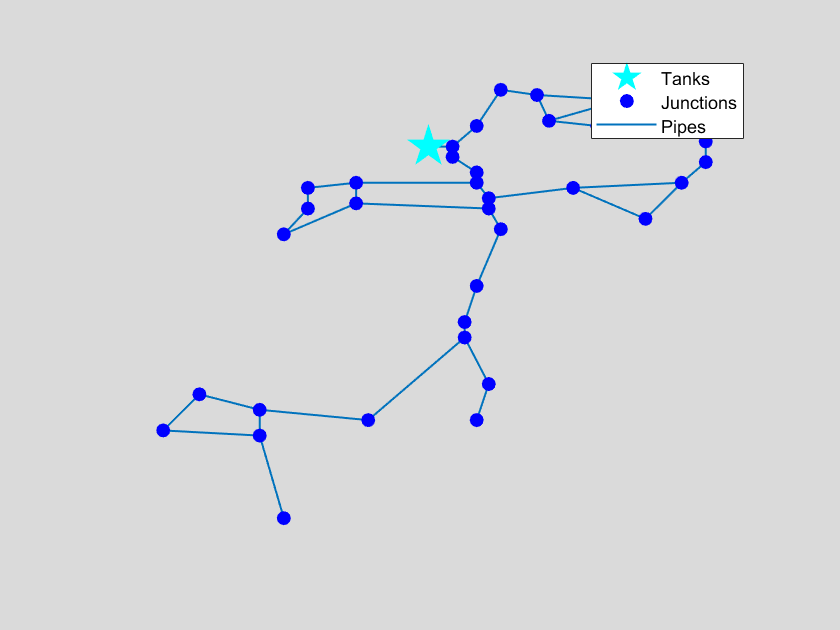

ans =   Axes with properties:

             XLim: [6.5000 60.5000]
             YLim: [-4.3000 95.3000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


G.plot

% Number of simulations
Nsim = 50

Nsim = 50

% Get nominal base demands
base_demands = G.getNodeBaseDemands{1}

base_demands =  -694.4000    8.0000   14.0000    8.0000    8.0000    5.0000    4.0000    9.0000   14.0000    5.0000   34.7800   16.0000    2.0000    2.0000    2.0000   20.0000   20.0000   20.0000    5.0000   19.0000   16.0000   10.0000    8.0000   11.0000    6.0000    8.0000         0    7.0000    3.0000   17.0000   17.0000    1.5000    1.5000         0    1.0000         0


% 5% max uncertainty in base demands
eta_bar = 0.05

eta_bar = 0.0500


% initialize matrix to save MCS pressures
Pmcs = {};
Qmcs = {};

**Run the simulation and store the pressure results**

for i = 1:Nsim
    %compute new base demands
    delta_bd = (2*rand(1,length(base_demands))-1).*eta_bar.*base_demands;
    new_base_demands = base_demands + delta_bd;
    G.setNodeBaseDemands(new_base_demands);
    Pmcs{i} = G.getComputedHydraulicTimeSeries.Pressure;
    Qmcs{i} = G.getComputedQualityTimeSeries.NodeQuality;
    disp(['Epoch ',int2str(i)])
end

Epoch 1
Epoch 2
Epoch 3
Epoch 4
Epoch 5
Epoch 6
Epoch 7
Epoch 8
Epoch 9
Epoch 10
Epoch 11
Epoch 12
Epoch 13
Epoch 14
Epoch 15
Epoch 16
Epoch 17
Epoch 18
Epoch 19
Epoch 20
Epoch 21
Epoch 22
Epoch 23
Epoch 24
Epoch 25
Epoch 26
Epoch 27
Epoch 28
Epoch 29
Epoch 30
Epoch 31
Epoch 32
Epoch 33
Epoch 34
Epoch 35
Epoch 36
Epoch 37
Epoch 38
Epoch 39
Epoch 40
Epoch 41
Epoch 42
Epoch 43
Epoch 44
Epoch 45
Epoch 46
Epoch 47
Epoch 48
Epoch 49
Epoch 50


**How pressure fluctuates?**

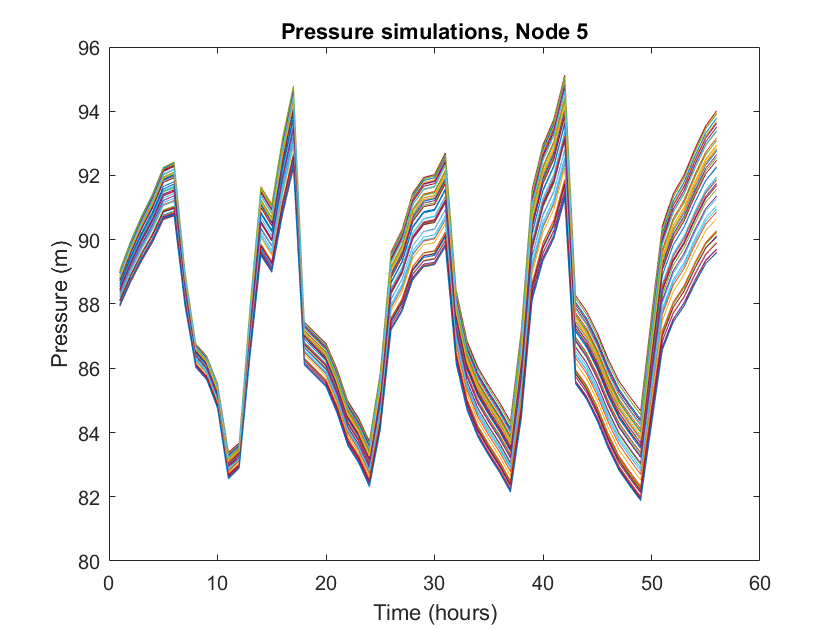

node = 5;
figure
for i = 1:Nsim
    Pmulti(:,i) = Pmcs{i}(:,node);
    plot(Pmulti(:,i))
    hold on
end
title(['Pressure simulations, Node ',int2str(node)])
xlabel('Time (hours)')
ylabel('Pressure (m)')

**Compute upper and lower bounds**

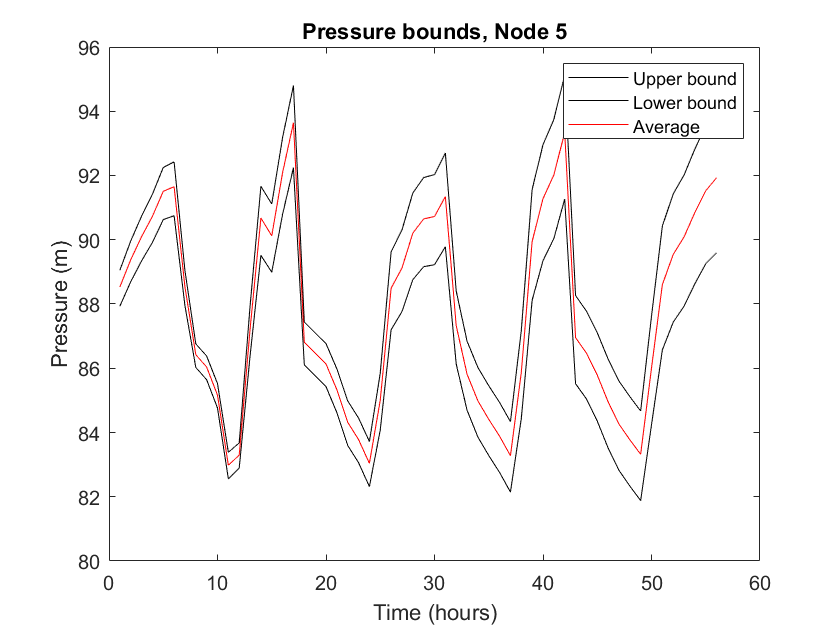

ub = max(Pmulti,[],2);
lb = min(Pmulti,[],2);
meanb = mean(Pmulti,2);

figure
plot(ub,'k')
hold on
plot(lb,'k')
plot(meanb, 'r')
legend('Upper bound','Lower bound', 'Average')
title(['Pressure bounds, Node ',int2str(node)])
xlabel('Time (hours)')
ylabel('Pressure (m)')

**How quality fluctuates?**

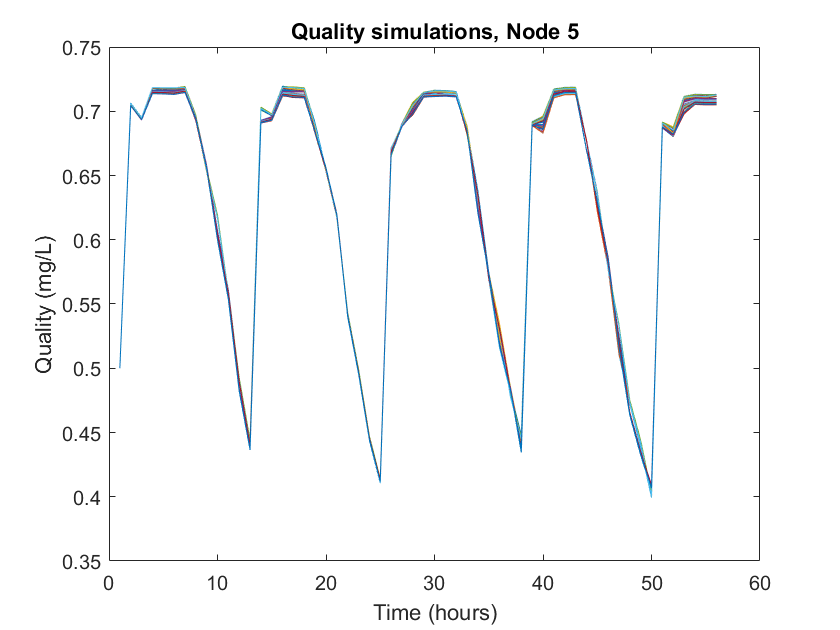

node = 5;
figure
for i = 1:Nsim
    Qmulti(:,i) = Qmcs{i}(:,node);
    plot(Qmulti(:,i))
    hold on
end
title(['Quality simulations, Node ',int2str(node)])
xlabel('Time (hours)')
ylabel('Quality (mg/L)')

**Compute upper and lower bounds**

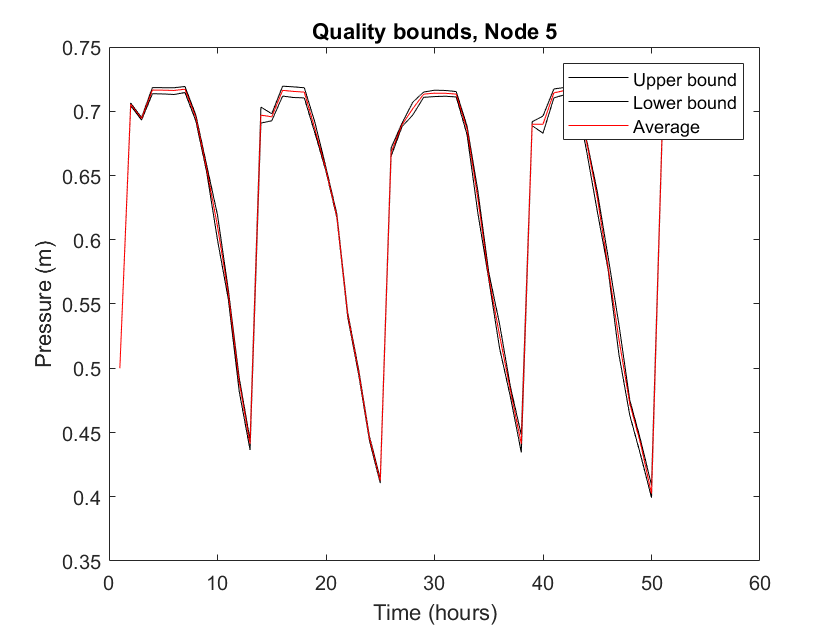

ub = max(Qmulti,[],2);
lb = min(Qmulti,[],2);
meanb = mean(Qmulti,2);

figure
plot(ub,'k')
hold on
plot(lb,'k')
plot(meanb, 'r')
legend('Upper bound','Lower bound', 'Average')
title(['Quality bounds, Node ',int2str(node)])
xlabel('Time (hours)')
ylabel('Pressure (m)')

### How to simulate a contamination event

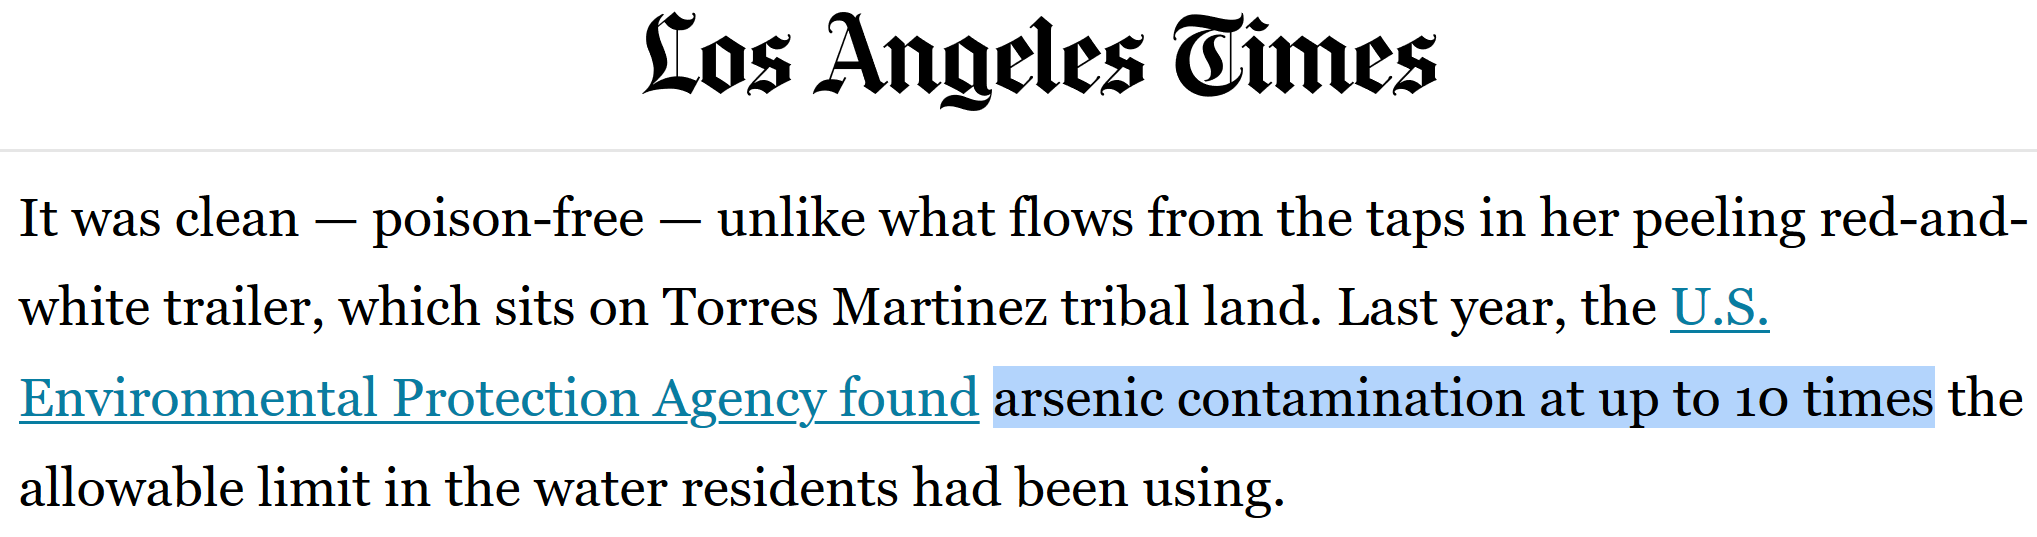

**Create an arsenite contamination event**

G = epanet('BWSN_Network_1.inp'); % Load EPANET Input file

EPANET version {20200} loaded (EMT version {dev2.2}).
Loading File "BWSN_Network_1.inp"...
Input File "BWSN_Network_1.inp" loaded sucessfuly.


G.loadMSXFile('Arsenite.msx'); % Load MSX file

Prepare the simulations

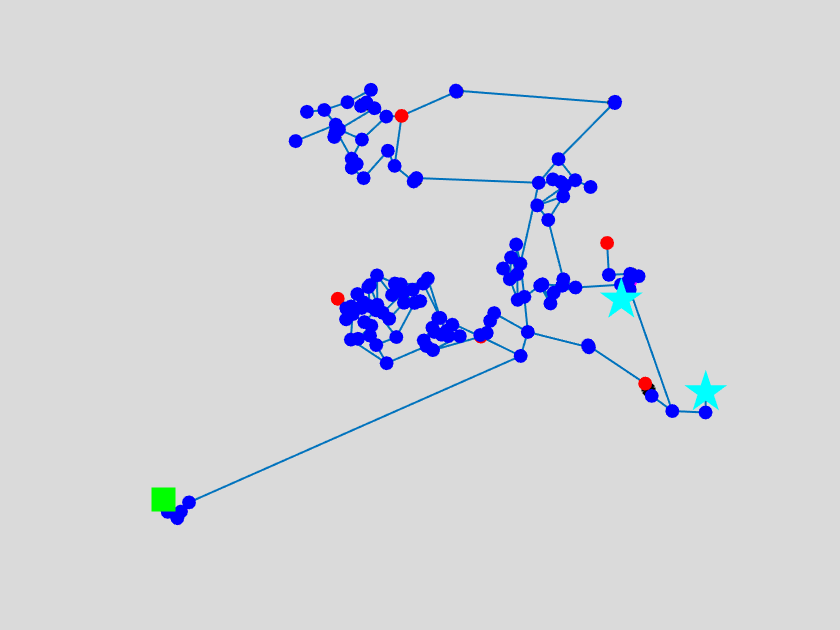

% Sensor locations
sensor_id = {'JUNCTION-17', 'JUNCTION-83', 'JUNCTION-122', 'JUNCTION-31', 'JUNCTION-45'};
sensor_index = G.getNodeIndex(sensor_id);

figure
G.plot('highlightnode', sensor_id);


% Simulation Setup
t_d = 5; % days
G.setTimeSimulationDuration(t_d*24*60*60); % Set simulation duration of 5 days
G.setMSXTimeStep(3600) 

MSX unloaded


A contamination scenario needs a location (node), a contaminant concentration and a time profile (start and end time)

injection_node = {'JUNCTION-23'}

injection_node = 1×1 cell array
    {'JUNCTION-23'}


injection_conc = 0.05

injection_conc = 0.0500

injection_start_time = 150 

injection_start_time = 150

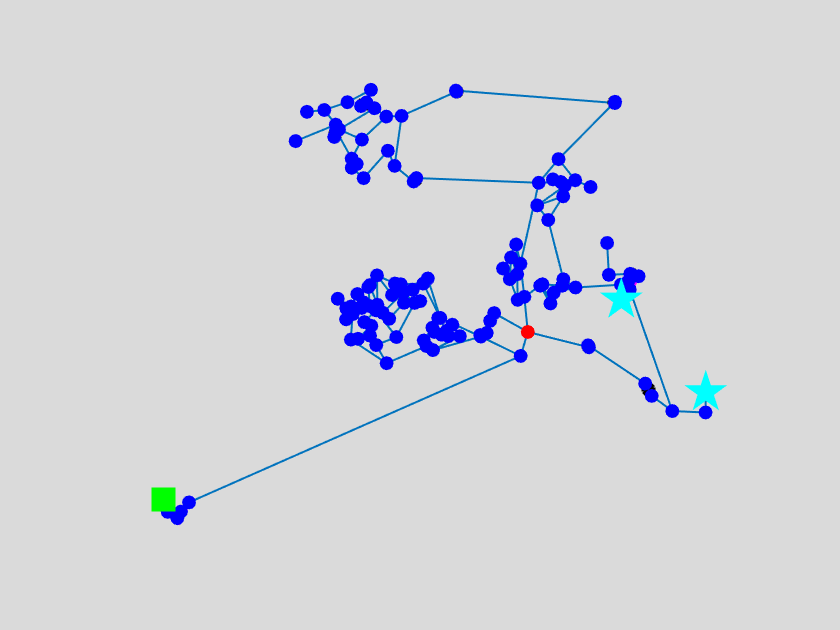

figure
G.plot('highlightnode', injection_node);

**Initialize the contamination vector (binary)**

as3_pat = zeros(1, t_d*48); % initialize the vector
as3_pat(injection_start_time:end) = 1; % create the injection pattern 

**Simulate the contamination of water with arsenite**

% Specify Arsenite injection source
G.setMSXSources(injection_node, 'AsIII', 'Setpoint', injection_conc, 'AS3PAT'); 
% Set pattern for injection
G.setMSXPattern('AS3PAT',as3_pat);
% Solve hydraulics and MSX quality dynamics
Qmsx = G.getMSXComputedQualityNode(sensor_index); 

**Plot the results**

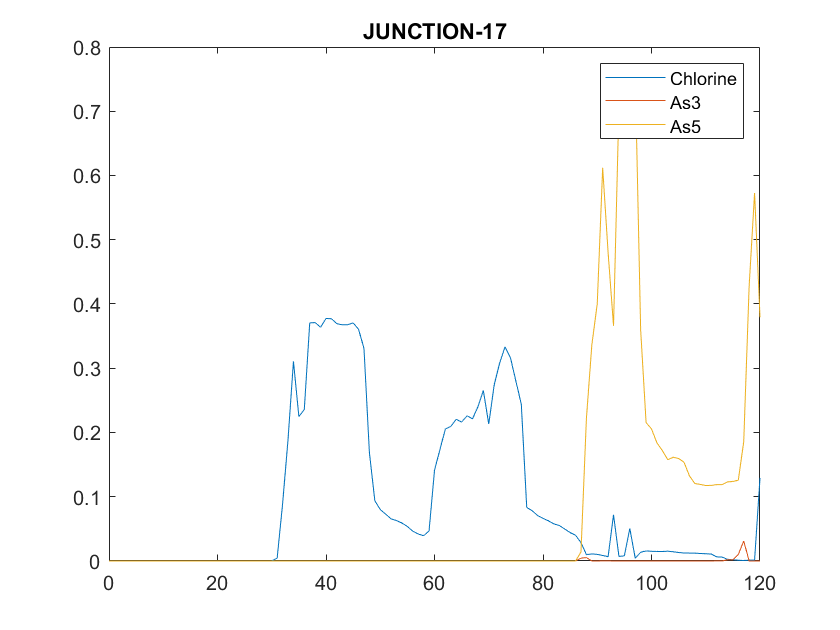

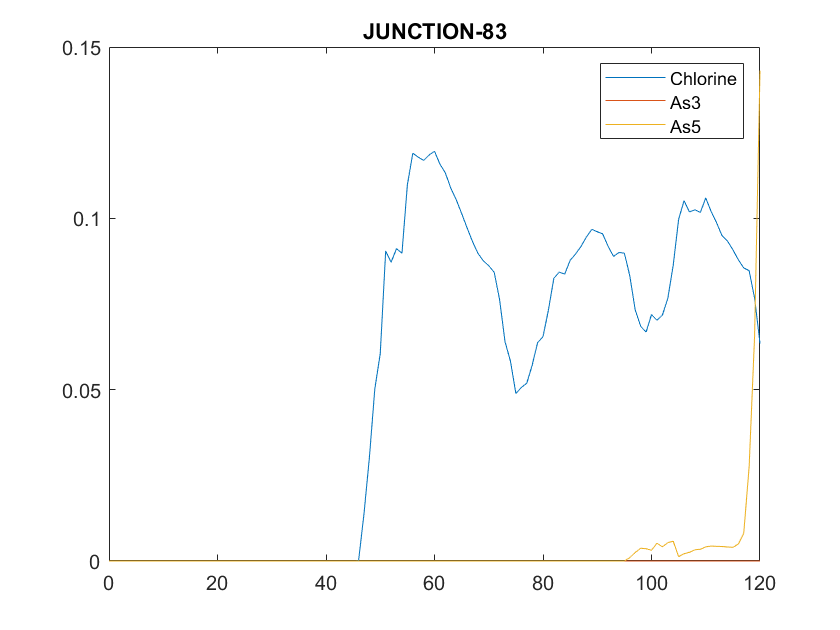

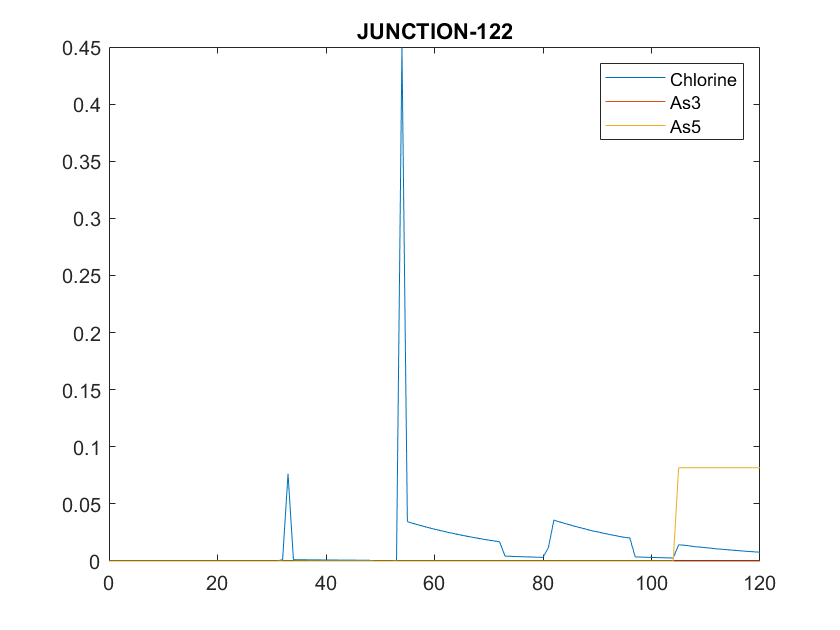

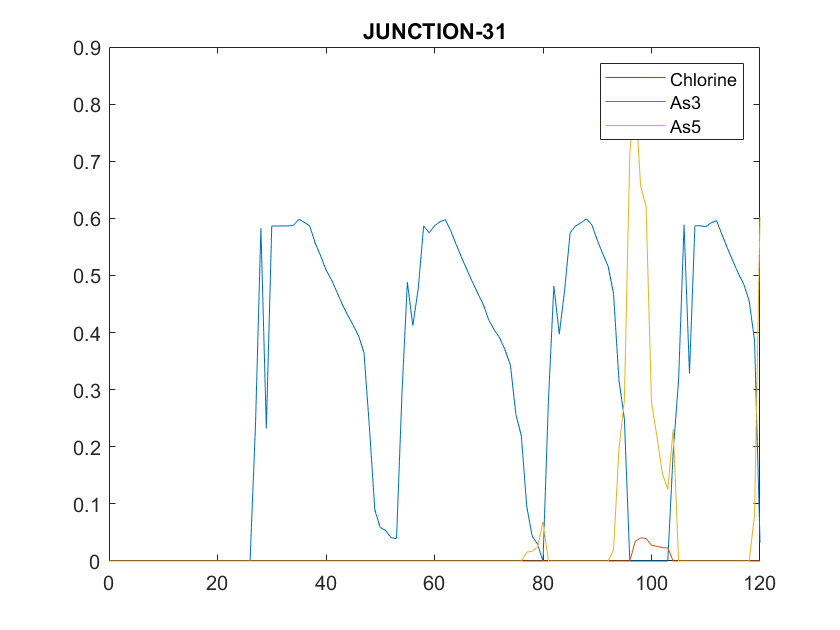

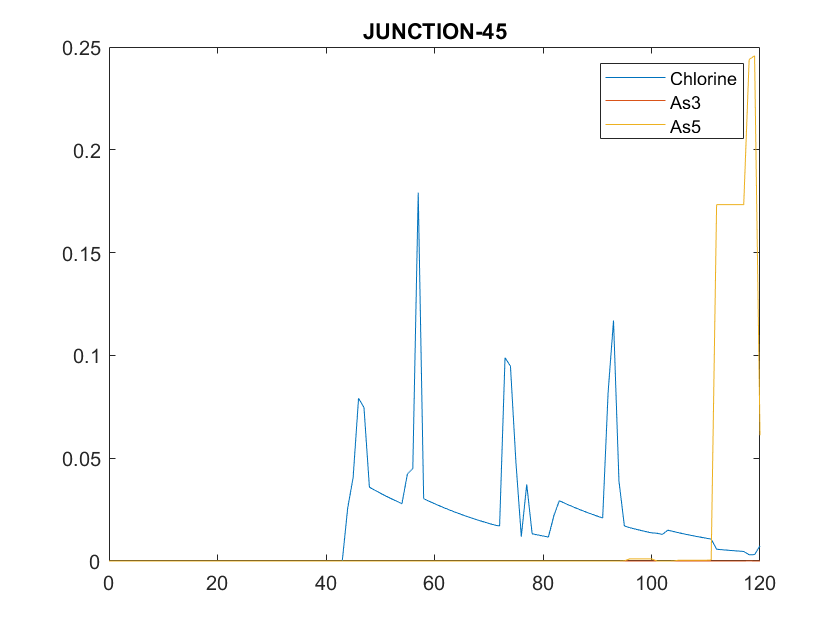

for i = 1:5
    figure
    plot(Qmsx.Time/3600, Qmsx.Quality{i})
    legend('Chlorine','As3', 'As5')
    title(sensor_id(i))
end

### **Monte Carlo simulations for contamination detection**

**Initialize the simulation**

rng(1)

%% Load EPANET Network and MSX
G = epanet('BWSN_Network_1.inp'); % Load EPANET Input file

EPANET version {20200} loaded (EMT version {dev2.2}).
Loading File "BWSN_Network_1.inp"...
Input File "BWSN_Network_1.inp" loaded sucessfuly.


G.loadMSXFile('Arsenite.msx'); % Load MSX file

% Sensor locations
sensor_id = {'JUNCTION-17', 'JUNCTION-83', 'JUNCTION-122', 'JUNCTION-31', 'JUNCTION-45'}

sensor_id = 1×5 cell array
    {'JUNCTION-17'}    {'JUNCTION-83'}    {'JUNCTION-122'}    {'JUNCTION-31'}    {'JUNCTION-45'}


sensor_index = G.getNodeIndex(sensor_id);

%% Simulation Setup
t_d = 5 % days

t_d = 5

G.setTimeSimulationDuration(t_d*24*60*60); % Set simulation duration of 5 days

%% Get Network data
demand_pattern = G.getPattern;
roughness_coeff = G.getLinkRoughnessCoeff;
node_id = G.getNodeNameID;

G.setMSXTimeStep(3600)

MSX unloaded


**Setup uncertainties**

%% Scenarios
Ns = 20; % Number of scenarios to simulate
u_p = 0.20 % pattern uncertainty

u_p = 0.2000

u_r = 0.20 % roughness coefficient uncertainty

u_r = 0.2000

**Create the scenarios - first without contamination, to compute the bounds**

max_inj_conc = 0.0

max_inj_conc = 0

inj_start_time = 2*48 % after day 2 (Dt = 30min)

inj_start_time = 96

inj_duration = 24 % maximum duration of 12 hours

inj_duration = 24

% Injection location, magnitude, start time, duration 
inj_sc=[randi(G.NodeCount,Ns,1), max_inj_conc*rand(Ns,1), randi(48,Ns,1)+inj_start_time, randi(inj_duration,Ns,1)] 

inj_sc =     54     0   144     3
    93     0   132    10
     1     0   110    17
    40     0   134    10
    19     0   101     2
    12     0   118    13
    25     0   140    16
    45     0   111    13
    52     0   110    23
    70     0   103    15


**Run epochs**

for i = 1:Ns
    disp(['Iteration ', int2str(i)])
    
    % Randomize demands
    r_p = -u_p + 2*u_p.*rand(size(demand_pattern,1),size(demand_pattern,2));
    new_demand_pattern = demand_pattern + demand_pattern.*r_p;
    G.setPatternMatrix(new_demand_pattern); % Set new patterns
    
    % Randomize pipe roughness
    r_r = -u_r + 2*u_r.*rand(size(roughness_coeff,1),size(roughness_coeff,2));
    new_roughness_coeff = roughness_coeff + roughness_coeff.*r_r;
    G.setLinkRoughnessCoeff(new_roughness_coeff); % Set new roughness coefficients
    
    % Randomize injection
    %G.setMSXSources(node_id(inj_sc(i,1)), 'AsIII', 'Setpoint', inj_sc(i,2), 'AS3PAT'); % Specify Arsenite injection source
    %as3_pat = zeros(1, t_d*48);
    %as3_pat(inj_sc(i,3):(inj_sc(i,3)+inj_sc(i,4))) = 1; % 
    %G.setMSXPattern('AS3PAT',as3_pat); % Set pattern for injection
    QQ{i} = G.getMSXComputedQualityNode(sensor_index); % Solve hydraulics and MSX quality dynamics
    %G.setMSXSources(node_id(inj_sc(i,1)), 'AsIII', 'Setpoint', 0, 'AS3PAT'); % Reset injection source
end

Iteration 1
Iteration 2
Iteration 3
Iteration 4
Iteration 5
Iteration 6
Iteration 7
Iteration 8
Iteration 9
Iteration 10
Iteration 11
Iteration 12
Iteration 13
Iteration 14
Iteration 15
Iteration 16
Iteration 17
Iteration 18
Iteration 19
Iteration 20


**Plot the results without contaminations**

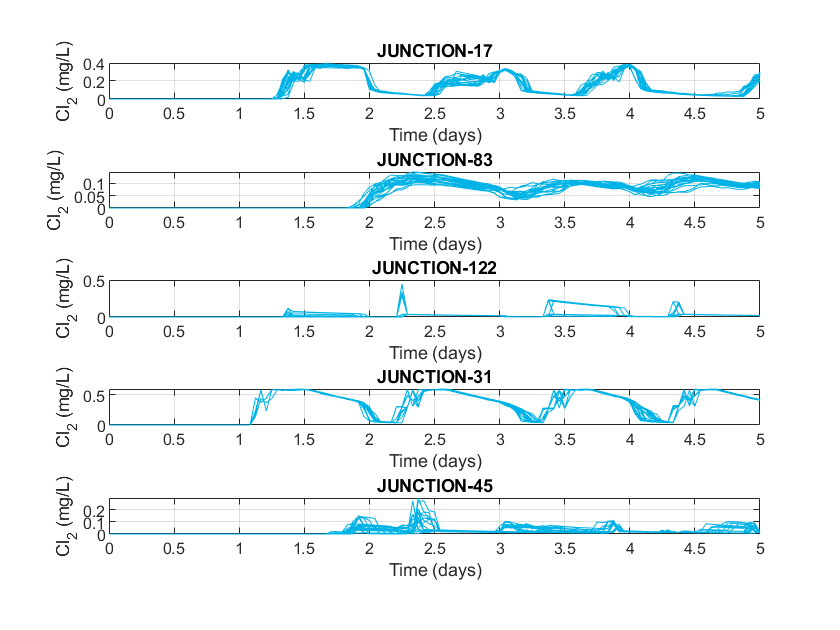

figure
for i = 1:Ns
    for j = 1:length(sensor_index)
       subplot(5,1,j)
       plot(QQ{i}.Time/24/60/60, QQ{i}.Quality{j}(:,1),'-','Color',[0,0.7,0.9]); hold on; grid on
       Qtable{j}(:,i) = QQ{i}.Quality{j}(:,1);
    end
end
for i = 1:length(sensor_index)
   subplot(5,1,i)
   title(sensor_id{i})
   ylabel('Cl_2 (mg/L)')
   xlabel('Time (days)')
end

**Compute the intervals for each sensor**

for j = 1:length(sensor_index)
    % Upper Bound
    UBQ(:,j) = max(Qtable{j},[],2); 
    % Lower Bound    
    LBQ(:,j) = min(Qtable{j},[],2);
end

**Plot the intervals**

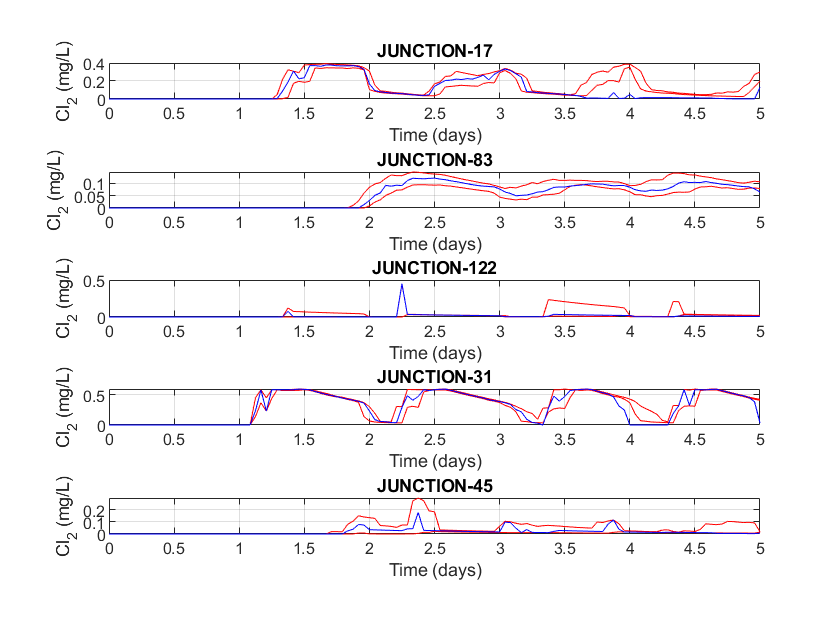

figure
for j = 1:length(sensor_index)
       subplot(5,1,j)
       plot(QQ{i}.Time/24/60/60, UBQ(:,j),'r-'); 
       hold on; 
       plot(QQ{i}.Time/24/60/60, LBQ(:,j),'r-');

       % plot the contamination event simulated earier
       plot(Qmsx.Time/24/60/60, Qmsx.Quality{j}(:,1), 'b-')
       grid on
end
for i = 1:length(sensor_index)
   subplot(5,1,i)
   title(sensor_id{i})
   ylabel('Cl_2 (mg/L)')
   xlabel('Time (days)')
end

### **Contamination detection**

Compare what the model predicts, with what the (chlorine) sensors measure. If the difference is significantly larger, then put a fault warning.


$$e = y - \hat{y}$$


if $e > \bar{\epsilon}$ then fault flag $\phi(k) = 1$

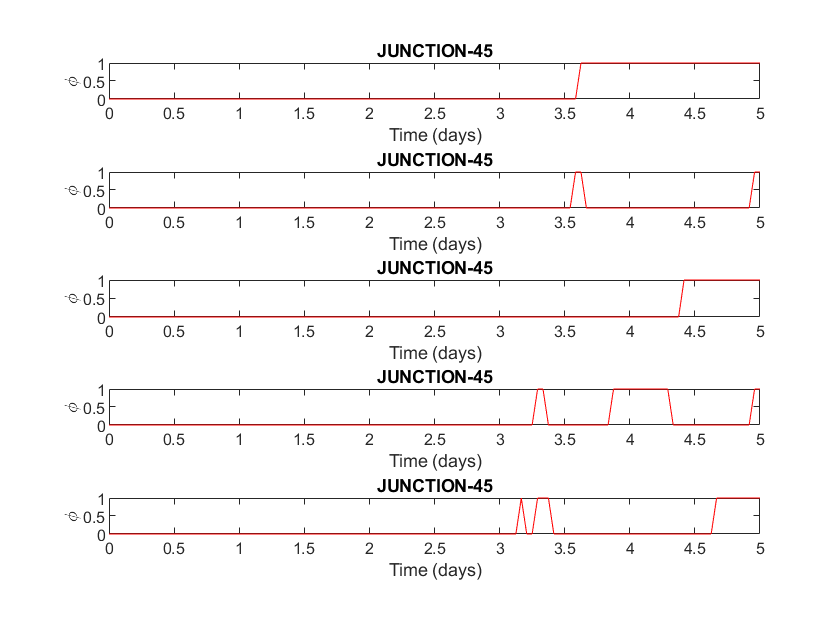

figure
for j = 1:length(sensor_index)   
    % difference between the lower bound and the measured value
    e = LBQ(:,j) - Qmsx.Quality{j}(:,1);
    % create the \phi signal by putting 1 when the error is > 0
    phi = e>0;

    % plot the results
    subplot(5,1,j)
    plot(Qmsx.Time/24/60/60, phi, 'r-')
    title(sensor_id{i})
    ylabel('\phi')
    xlabel('Time (days)')
end